# Thermoeconomic Analysis Demo

Use ThermoeconomicAnalysis function to compute the exergy cost of a plant

#### Select and check the model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data=ReadDataModel(filename);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(4));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));
CostTables='ALL';

CostTables = 'ALL'

#### Compute Cost Analysis

res=ThermoeconomicAnalysis(data,'State',State, ...
    'CostTables',CostTables,'ResourceSample',ResourceSample);

#### Show Results

printResults(res);

Process Exergy Cost

 Key        P*(MW)     Pe*(MW)     Pr*(MW)      F*(MW)      R*(MW)
-------------------------------------------------------------------
 COMB       86.381      83.688       2.693      83.688       2.693
 COMP       56.906      54.268       2.638      56.622       0.283
 TURB      109.922     105.352       4.571     109.639       0.283
 PHTR       35.975      34.296       1.679      35.692       0.283
 HRSG       30.388      29.200       1.188      30.388       0.000
 STCK        3.543       3.405       0.139       3.543       0.000


Process Unit Exergy Cost

 Key      kP*(J/J)   kPe*(J/J)   kPr*(J/J)    kF*(J/J)    kR*(J/J)      k(J/J)
-------------------------------------------------------------------------------
 COMB       1.4971      1.4504      0.0467      1.0000      0.0467      1.4504
 COMP       1.9580      1.8672      0.0908      1.7767      0.0098      1.0966
 TURB       1.7767      1.7028      0.0739      1.6977      0.0046      1.0438
 PHTR       1.9108

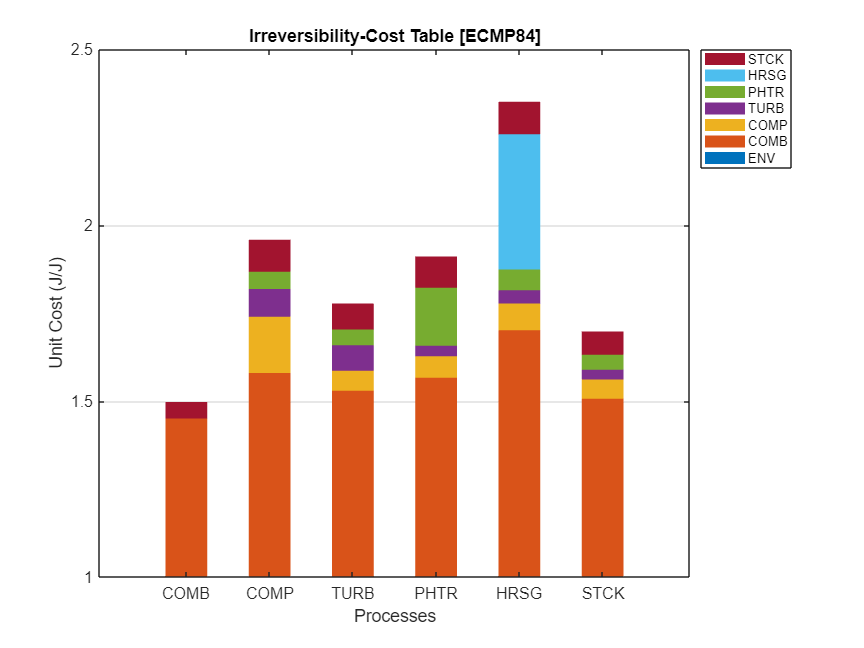

graphCost(res);